% priprava podatkov
data = load('VAJA3.mat');

% Priprava podatkov
A_FLOW = data.A_FLOW;
T_H2O = data.T_H2O;
C_ACID = data.C_ACID;
I_EFF = data.I_EFF;
X = [A_FLOW, T_H2O, C_ACID];
Y = I_EFF;

% Izbira standardizacijskih metod
standardization_methods = ["min-max", "z-score", "none"];




% Zanka za LSE
for i = 1:length(standardization_methods)
    n = standardization_methods(i);
    
    % Standardizacija podatkov
    [X_n, Y_n] = abc(X, Y, n);
    
    % Dodajanje stolpca enic za presledek
    X_n = [X_n, ones(size(X_n, 1), 1)];
    X_c = [X, ones(size(X, 1), 1)];

    % Izračun parametrov beta z metodo LSE
    beta_hat_std = (X_n' * X_n) \ (X_n' * Y_n);

    % Transformacija parametrov nazaj v originalni prostor, če je potrebno
    if n == "min-max"
        min_X = min(X);
        max_X = max(X);
        min_Y = min(Y);
        max_Y = max(Y);

        beta_hat_X = beta_hat_std(1:end-1)' .* (max_Y - min_Y) ./ (max_X - min_X);
        beta_hat_0 = beta_hat_std(end) * (max_Y - min_Y) + min_Y - sum(beta_hat_X .* min_X);
        beta_hat = [beta_hat_X, beta_hat_0];

        % Izračun predvidenih vrednosti I_EFF
        I_EFF_pred = X_c * beta_hat';

    elseif n == "z-score"
        mu_X = mean(X);
        sigma_X = std(X);
        mu_Y = mean(Y);
        sigma_Y = std(Y);

        beta_hat_X = beta_hat_std(1:end-1)' .* sigma_Y ./ sigma_X;
        beta_hat_0 = beta_hat_std(end) * sigma_Y + mu_Y - sum(beta_hat_X .* mu_X);
        beta_hat = [beta_hat_X, beta_hat_0];

        % Izračun predvidenih vrednosti I_EFF
        I_EFF_pred = X_c * beta_hat';
    elseif n == "none"
        beta_hat = beta_hat_std';
        I_EFF_pred = X_c * beta_hat';
    end

    % Izračun napake, kovariančne matrike in NRMSE
    error_LSE = I_EFF - I_EFF_pred;
    cov_matrix_LSE = pinv(X_c' * X_c) * (error_LSE' * error_LSE) / (size(X_c, 1) - size(X_c, 2));
    NRMSE_LSE = sqrt(sum((error_LSE).^2) / (size(X, 1))) / std(Y);
    STD_LSE = std(error_LSE);

    % Prikaz rezultatov
    disp(['LSE Standardization Method: ', n]);
    fprintf('Regression Coefficients: %f %f %f %f\n', beta_hat);
    fprintf('parameter variance: %f %f %f %f\n', diag(cov_matrix_LSE));
    fprintf('Normalized Root Mean Squared Error (NRMSE):  %.3f\n', NRMSE_LSE);
    fprintf('Error Variance: %.3f, Error Bias: %.3f, Error Standard deviation: %.3f\n', var(error_LSE), mean(error_LSE), STD_LSE);

    % Prikaz pričakovanih in izračunanih vrednosti
    subplot(1, 3, i);
    plot(1:length(I_EFF), I_EFF, 'bo-', 'DisplayName', 'Expected Y (I_{EFF})');
    hold on;
    plot(1:length(I_EFF), I_EFF_pred, 'r*-', 'DisplayName', 'Calculated Y (I_{EFF_{pred}})');
    xlabel('Meritev');
    ylabel('Inverzna natančnost');
    %title(sprintf('Standardization: %s', n));
    ylim([min(I_EFF) - 0.1 * range(I_EFF), max(I_EFF) + 0.1 * range(I_EFF)]);
    xlim([0, length(I_EFF) + 1]);
    hold off;
end

% Load data
data = load('VAJA3.mat');

% Data Preparation
X = [data.A_FLOW, data.T_H2O, data.C_ACID];
Y = data.I_EFF;

% Choose the standardization methods
standardization_methods = ["min-max"];

% Initialize figure for plotting
figure;

% Loop through each standardization method
for i = 1:length(standardization_methods)
    n = standardization_methods(i);
    
    %% PCA Regression
    % Standardize the data
    [X_n, Y_n] = abc(X, Y, n);

    % Combine and center the data
    Z = [X_n, Y_n];
    nn = size(Z, 1);
    Z_centered = Z - mean(Z);

    % Calculate the covariance matrix
    F = (Z_centered' * Z_centered) / (nn - 1);

    % Perform Singular Value Decomposition (SVD)
    [P, ~] = svd(F);

    % Get the coefficients of the first principal component
    coeff = P(:, end);

    % Calculate the explicit model coefficients
    if n == "min-max" 
        a = coeff(1:end-1)' ./ coeff(end);
        c = -a .* (max(Y) - min(Y)) ./ (max(X) - min(X));
        d = sum(a .* (mean(X_n) .* (max(Y) - min(Y)))) + mean(Y_n) * (max(Y) - min(Y)) + min(Y) + (max(Y) - min(Y)) .* a ./ (max(X) - min(X)) * min(X)';
    elseif n == "z-score"
        a = coeff(1:end-1)' ./ coeff(end);
        c = -a .* std(Y) ./ std(X);
        d = sum(a .* (mean(X_n) .* std(Y))) + mean(Y_n) * std(Y) + mean(Y) + std(Y) .* a ./ std(X) * mean(X)';
    else
        c = -coeff(1:end-1)' ./ coeff(end);
        d = mean(Y_n) - sum(c .* mean(X_n));
    end

    % Construct the PCA model coefficients
    model_PCA_poly = [c d];

    % Calculate predicted I_EFF
    model_PCA = sum(model_PCA_poly .* horzcat(X, ones(size(X, 1), 1)), 2);

    % Calculate the error and NRMSE
    error_PCA = Y - model_PCA;
    NRMSE_PCA = sqrt(sum((error_PCA).^2) / size(X, 1)) / std(Y);
    STD_PCA = std(error_PCA);

    % Display results
    disp(['PCA Standardization Method: ', n]);
    fprintf('Regression Coefficients: %f %f %f %f\n', model_PCA_poly);
    fprintf('Normalized Root Mean Squared Error (NRMSE):  %.3f\n', NRMSE_PCA);
    fprintf('Error Variance: %.3f, Error Bias: %.3f, Error Standard deviation %.3f\n', var(error_PCA), mean(error_PCA), STD_PCA);

    % Plot the expected Y and calculated Y
    subplot(1, 3, i);
    plot(1:length(Y), Y, 'bo-', 'DisplayName', 'Expected Y (I_{EFF})');
    hold on;
    plot(1:length(Y), model_PCA, 'r*-', 'DisplayName', 'Calculated Y (I_{EFF_{pred}})');
    xlabel('Meritev');
    ylabel('Inverzna natančnost');
    title(sprintf('Standardization: %s', n));
    ylim([min(Y) - 0.1 * range(Y), max(Y) + 0.1 * range(Y)]);
    xlim([0, length(Y) + 1]);
    hold off; 
end

% Adjust figure size to 30x10
set(gcf, 'Position', [100, 100, 3000, 1000]);

% Add common legend below the subplots
%legend('Expected Y (I_{EFF})', 'Calculated Y (I_{EFF_{pred}})', 'Orientation', 'horizontal', 'Position', [0.35, -0.1, 0.3, 0.05]);

%sgtitle('Comparison of Expected and Calculated I_{EFF} for Different Standardizations (PCA)');


## Problem kolinearnosti

% Initialize storage for parameters
M = 21;
params_LSE = zeros(M, 4);
params_PCR = zeros(M, 4);

for i = 1:M
    % Add new measurement with noise
    X_additional = 2 * T_H2O + 6 + 0.1 * randn(size(T_H2O, 1), 1);
    X = [A_FLOW, T_H2O, C_ACID, X_additional];
    Y = I_EFF;

    % Standardization
    [X_n, Y_n] = abc(X, Y, "z-score"); % Uporabi "z-score" standardizacijo

    %% LSE
    theta_LSE = (X_n' * X_n) \ (X_n' * Y_n);
    params_LSE(i, :) = theta_LSE';

    %% PCR
    % Combine and center the data
    Z = [X_n];
    nn = size(Z, 1);
    Z_centered = Z - mean(Z);

    % Calculate the covariance matrix
    F = (Z_centered' * Z_centered) / (nn - 1);

    % Perform SVD
    [P, D] = svd(F);

    % Remove the principal component with negligible impact (last component)
    P_reduced = P(:, 1:end-1);

    % Transform the original data into the principal component space
    T = X_n * P_reduced;

    % Calculate parameters in the reduced principal component space
    theta_PCR_reduced = (T' * T) \ (T' * Y_n);

    % Transform parameters back to the original space
    theta_PCR = P_reduced * theta_PCR_reduced;
    params_PCR(i, :) = theta_PCR';
end

% Calculate the mean over all iterations
theta_LSE_mean = mean(params_LSE)';
theta_PCR_mean = mean(params_PCR)';

% Calculate modeled values and errors
y_pred_LSE = X_n * theta_LSE_mean;
y_pred_PCR = X_n * theta_PCR_mean;

error_LSE = y_pred_LSE - Y_n;
error_PCR = y_pred_PCR - Y_n;

% NRMSE calculation
NRMSE_LSE = sqrt(sum((error_LSE).^2) / size(X_n, 1)) / std(Y_n);
NRMSE_PCR = sqrt(sum((error_PCR).^2) / size(X_n, 1)) / std(Y_n);

% Theoretical variances for LSE
cov_matrix_LSE = pinv(X_n' * X_n) * (error_LSE' * error_LSE) / (size(X_n, 1) - size(X_n, 2));
variance_LSE = diag(cov_matrix_LSE);

% Estimate variances for PCR from experiments
variance_PCR = var(params_PCR);

% Display results
disp('LSE Method:');

LSE Method:


fprintf('Mean Regression Coefficients: %f %f %f %f\n', theta_LSE_mean);

Mean Regression Coefficients: 0.643771 0.293548 -0.081451 0.110528


fprintf('Normalized Root Mean Squared Error (NRMSE): %.3f\n', NRMSE_LSE);

Normalized Root Mean Squared Error (NRMSE): 0.287


fprintf('Theoretical Variance of Parameters: %f %f %f %f\n', variance_LSE);

Theoretical Variance of Parameters: 0.015894 15.632943 0.007016 15.466087



disp('PCR Method:');

PCR Method:


fprintf('Mean Regression Coefficients: %f %f %f %f\n', theta_PCR_mean);

Mean Regression Coefficients: 0.645011 0.201374 -0.080080 0.201196


fprintf('Normalized Root Mean Squared Error (NRMSE): %.3f\n', NRMSE_PCR);

Normalized Root Mean Squared Error (NRMSE): 0.287


fprintf('Estimated Variance of Parameters: %f %f %f %f\n', variance_PCR);

Estimated Variance of Parameters: 0.000002 0.000001 0.000001 0.000003


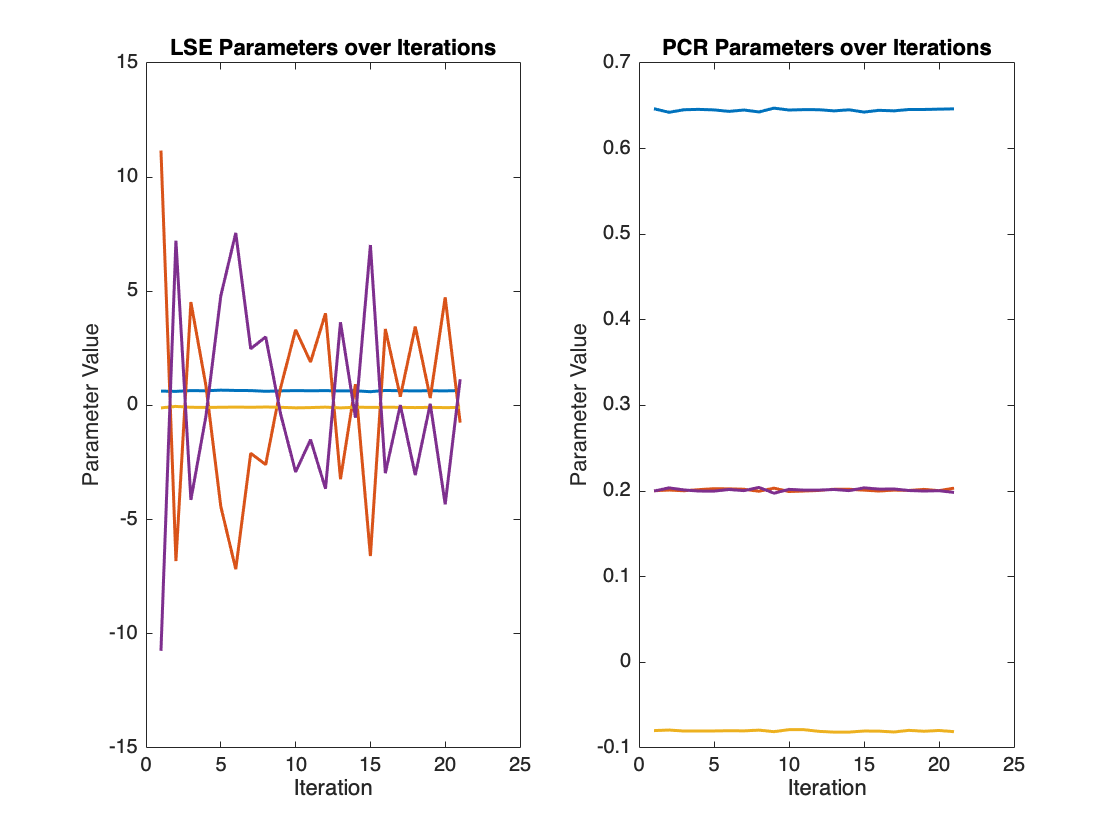


% Comparison plots
figure;
subplot(1, 2, 1);
plot(1:M, params_LSE, 'LineWidth', 1.5);
title('LSE Parameters over Iterations');
xlabel('Iteration');
ylabel('Parameter Value');

subplot(1, 2, 2);
plot(1:M, params_PCR, 'LineWidth', 1.5);
title('PCR Parameters over Iterations');
xlabel('Iteration');
ylabel('Parameter Value');


% Analysis of collinearity
R = corrcoef(X);
disp('Correlation Matrix of the Features:');

Correlation Matrix of the Features:


disp(R);

    1.0000    0.7819    0.5001    0.7792
    0.7819    1.0000    0.3909    0.9998
    0.5001    0.3909    1.0000    0.3926
    0.7792    0.9998    0.3926    1.0000



% Funkcija za standardizacijo podatkov
function [X_n, Y_n] = abc(X,Y,n)
    if n == "min-max"
        X_n = (X - min(X)) ./ (max(X) - min(X));
        Y_n = (Y - min(Y)) ./ (max(Y) - min(Y));
    elseif n == "z-score"
        X_n = (X - mean(X)) ./ std(X);
        Y_n = (Y - mean(Y)) ./ std(Y);
    elseif n == "none"
        X_n = X;
        Y_n = Y;
    end
end

% Funkcija za povrnitev standardiziranih podatkov nazaj v originalne vrednosti
function Y_n = abc_rev(Y,n,Y_orig)
    if n == "min-max"
        Y_n = (Y*(max(Y_orig) - min(Y_orig))) + min(Y_orig);
    elseif n == "z-score"
        Y_n = (Y .* std(Y_orig)) + mean(Y_orig);
    end
end
